## **Loudspeaker modeling speed comparisons**

Francis Tiong    ftiong@mathworks.com

Copyright 2024 The MathWorks, Inc.

To quantitatively evaluate the temporal efficiency, two models that implements the same loudspeaker is used.  The "loudspeaker_simulink.slx" implents it in Simulink while the "loudspeaker_simscape.slx" implements it in Simscape. This livescript shows how the results are obtained.  

Here is a summary of the findings regarding the speed of execution: 

1, There is no significant difference between Simulink and Simscape implementations.

2, Using an analog signal source is faster than using a discrete signal source when the solver is in variable step mode.

3, No significant time difference in running the models in accelerator mode or even the rapid accelerator mode.

4, With a discrete signal source the model can then be executed with a solver that is in a fixed-step mode. Running in fixed-step mode is signifcantly faster than in variable step mode.

5, With the models in fixed-step mode they can be compiled into a standalone executable which runs at least 10x faster.

Using the Simulink Coder is the fastest implementation at the time of this writing.  Note that the use of external hardware SpeedGoat does not help in this model since the hardware is targeting running a digital system in fixed-step mode -- not using a differential equation solver.

Resutls obtained from MATLAB version 2023a running on a Lenova ThinkPad.

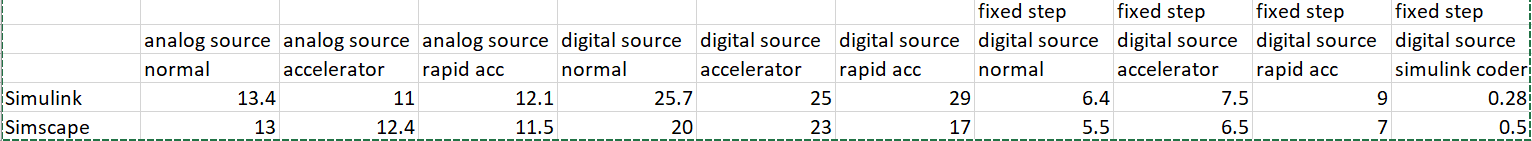


tim = tic;
sim("speaker_simulink");
toc(tim)

Elapsed time is 16.179560 seconds.


% 13.4


tim = tic;
sim("speaker_simulink");  % accelerator
toc(tim)

Elapsed time is 11.040287 seconds.


% 11


tim = tic;
sim("speaker_simulink");  % rapid accelerator


Build Summary

0 of 1 models built (1 models already up to date)
Build duration: 0h 0m 1.8747s


toc(tim)

Elapsed time is 14.768487 seconds.


% 12.1

% dsp chirp
tim = tic;
sim("speaker_simulink");
toc(tim)

Elapsed time is 31.286199 seconds.


% 25.7


% dsp chirp
tim = tic;
sim("speaker_simulink");  % accelerator
toc(tim)

Elapsed time is 24.815501 seconds.


% 25.


% dsp chirp
tim = tic;
sim("speaker_simulink");  % rapid accelerator


Build Summary

0 of 1 models built (1 models already up to date)
Build duration: 0h 0m 1.3736s


toc(tim)

Elapsed time is 28.841139 seconds.


% 29


% dsp chirp, fixed step
tim = tic;
sim("speaker_simulink");  %  
toc(tim)

Elapsed time is 6.344748 seconds.


% 6.4


% dsp chirp, fixed step
tim = tic;
sim("speaker_simulink");  %  acceleration
toc(tim)

Elapsed time is 7.550848 seconds.


% 7.5


% dsp chirp, fixed step
tim = tic;
sim("speaker_simulink");  % rapid acceleration


Build Summary

0 of 1 models built (1 models already up to date)
Build duration: 0h 0m 1.2214s


toc(tim)

Elapsed time is 8.866096 seconds.


% 9


slbuild("speaker_simulink");

### Starting build procedure for: speaker_simulink
### Generating code and artifacts to 'Model specific' folder structure
### Generating code into build folder: C:\Users\ftiong\OneDrive - MathWorks\Documents1\speakerModeling\speakerModels\st_model\SimscapeSpeed\speaker_simulink_grt_rtw
### Generated code for 'speaker_simulink' is up to date because no structural, parameter or code replacement library changes were found.
### Skipping makefile generation and compilation because C:\Users\ftiong\OneDrive - MathWorks\Documents1\speakerModeling\speakerModels\st_model\SimscapeSpeed\speaker_simulink.exe is up to date
### Successful completion of build procedure for: speaker_simulink

Build Summary

0 of 1 models built (1 models already up to date)
Build duration: 0h 0m 1.4947s



tim = tic;
!speaker_simulink.exe

 
** starting the model ** 
*** Log variable rt_tout has wrapped 480 times 
    using a circular buffer of size 1000 
** created speaker_simulink.mat ** 
 


toc(tim)

Elapsed time is 0.260077 seconds.


% 0.28

Test Simscape next


tim = tic;
sim("speaker_SS_simscape");
toc(tim)

Elapsed time is 18.408562 seconds.


tim = tic;
sim("speaker_simscape");
toc(tim)

Elapsed time is 12.717705 seconds.


% 13

tim = tic;
sim("speaker_simscape");  % accelerator
toc(tim)

Elapsed time is 16.676707 seconds.


% 12.4

tim = tic;
sim("speaker_simscape");  % rapid accelerator


Build Summary

0 of 1 models built (1 models already up to date)
Build duration: 0h 0m 1.9865s


toc(tim)

Elapsed time is 11.463237 seconds.


% 11.5


% dsp chirp
tim = tic;
sim("speaker_simscape");  %  
toc(tim)

Elapsed time is 20.938618 seconds.


% 20

% dsp chirp
tim = tic;
sim("speaker_simscape");  %  accelerator
toc(tim)

Elapsed time is 27.017787 seconds.


% 23

% dsp chirp
tim = tic;
sim("speaker_simscape");  % rapid accelerator


Build Summary

0 of 1 models built (1 models already up to date)
Build duration: 0h 0m 2.6057s


toc(tim)

Elapsed time is 17.329895 seconds.


% 17

% dsp chirp, fixed step
tim = tic;
sim("speaker_simscape");  %  
toc(tim)

Elapsed time is 5.495158 seconds.


% 5.5

% dsp chirp, fixed step
tim = tic;
sim("speaker_simscape");  %  accelerator
toc(tim)

Elapsed time is 7.555022 seconds.


% 6.5


% dsp chirp, fixed step
tim = tic;
sim("speaker_simscape");  % rapid accelerator


Build Summary

0 of 1 models built (1 models already up to date)
Build duration: 0h 0m 1.6798s


toc(tim)

Elapsed time is 6.906384 seconds.


% 7


% dsp chirp, fixed step
slbuild("speaker_simscape");

### Starting build procedure for: speaker_simscape
### Generating code and artifacts to 'Model specific' folder structure
### Generating code into build folder: C:\Users\ftiong\OneDrive - MathWorks\Documents1\speakerModeling\speakerModels\st_model\SimscapeSpeed\speaker_simscape_grt_rtw
### Generated code for 'speaker_simscape' is up to date because no structural, parameter or code replacement library changes were found.
### Saving binary information cache.
### Skipping makefile generation and compilation because C:\Users\ftiong\OneDrive - MathWorks\Documents1\speakerModeling\speakerModels\st_model\SimscapeSpeed\speaker_simscape.exe is up to date
### Successful completion of build procedure for: speaker_simscape

Build Summary

0 of 1 models built (1 models already up to date)
Build duration: 0h 0m 2.5099s


tim = tic;
!speaker_simscape.exe

 
** starting the model ** 
*** Log variable rt_tout has wrapped 480 times 
    using a circular buffer of size 1000 
** created speaker_simscape.mat ** 
 


toc(tim)

Elapsed time is 0.539586 seconds.



% 0.5